## Prac 1

clc; clear; close all

### Exercise 3.1

syms x t r

Function

% Use the independent variable x
fxz = x/2 - x/(1+x^2); % flow on the line
fx1 = r*x + (x^3)/(1+x^2);
fx = -x + x*exp(x)

$$fx = x\,{\mathrm{e}}^{x}-x$$

fx3 = 1 + 10*x + x^2;
fx4 = r + x - log(1+x);

Representations:

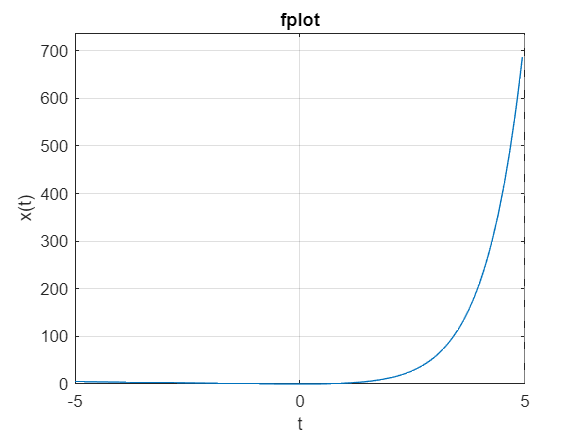

figure; fplot(fx,[-5,5]);
xlabel('t');ylabel('x(t)');grid on; title('fplot')

Fixed Points:

% Symbolically: It is exact but only sometimes works
Fpts1 = solve(fx) % use solve(??) for compute the fixed points

$$Fpts1 = 0$$

% Numerically: Always works but it is not exact: double precision (cuando
% no sabes nada o cuando lo sabes todo
Fpts2 = double(vpasolve(fx)) % Use double(vpasolve(??))

Fpts2 = 0

Stability:

% Guess a 
% Derivative:
fxd = diff(fx, x) % Get Derivative of fx respect to x

$$fxd = {\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x}-1$$

fxd_Fpts = subs(fxd,x,Fpts1) % Calculate derivative at Fixed Points

$$fxd\_Fpts = 0$$

disp('Stable Fixed Points:'); Fpts1(fxd_Fpts<0)   % Those Fixed Points with neg der

Stable Fixed Points:
 
ans =
 
[ empty sym ]
 


disp('Unstable Fixed Points:'); Fpts1(fxd_Fpts>0) % Those Fixed Points with pos der

Unstable Fixed Points:
 
ans =
 
[ empty sym ]
 


% Exploring Neighbourhood
epsilon = 1e-3;
neigB = [Fpts1-epsilon, Fpts1+epsilon] % Move Epsilon around the Fixed Points

$$neigB = \left(\begin{array}{cc} -\frac{1}{1000} & \frac{1}{1000} \end{array}\right)$$

fx_M = double(subs(fx,x,neigB))   % compute flow around fixed points

fx_M = 	1.0e+-5 *

    0.1000    0.1001


vec_neigB = diff(fx_M,1,2) % Estimate the slope

vec_neigB = 1.0000e-09

disp('Stable Fixed Points:'); stb = Fpts1(vec_neigB<0)% Those Fixed Points with neg slope

Stable Fixed Points:
 
stb =
 
[ empty sym ]
 


disp('Unstable Fixed Points:'); nstb = Fpts1(vec_neigB>0)% Those Fixed Points with neg eslope

Unstable Fixed Points:


$$nstb = 0$$

Phase Portrait

xi = -15; xf = 15; % initial and final x points -4 to 4
xsmp = 0:1*exp(2):5  % Vector with setp 1e^-2

xsmp = 0

figure; hold on;grid on; 
plot(xsmp,zeros(size(xsmp)),'k'); % plot black line in x-axis where the flow is
fplot(fx,[xi,xf],'b'); % fx between xi,xf
plot(stb,zeros(size(stb)),'o','MarkerFaceColor','r') % Plot filled circles fot stable fixed points
plot(nstb,zeros(size(nstb)),'ro') % Plot non-circles fot stable fixed points
rowPts = [-3,0,3] % points where a right/left marcker is going to be located

rowPts =     -3     0     3


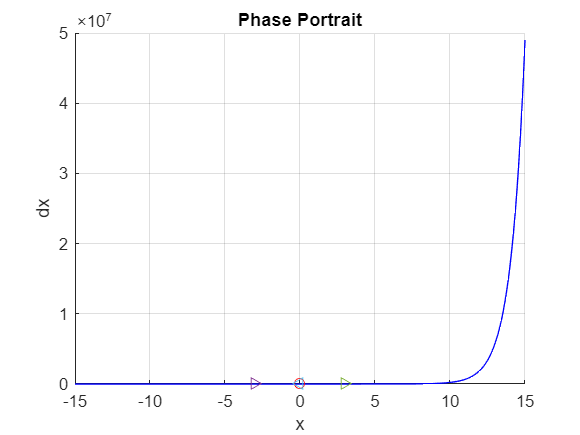

xsmp_r = xsmp(subs(fx,x,xsmp)>0); % Get those points with positive flow
xsmp_l = xsmp(subs(fx,x,xsmp)<0); % Get those points with negative flow
plot(xsmp_r,zeros(size(xsmp_r)),'g');plot(-3,0,'>');plot(3,0,'>'); % plot positve in green
plot(xsmp_l,zeros(size(xsmp_l)),'m');plot(0,0,'<'); % plot negative in magenta
xlabel('x'); ylabel('dx'); grid on; title('Phase Portrait');

Trajectories using Numeric Runge-Kutta ODE45 method

t0 = 0; tf = 1; % initial and final time 0 1
fN_lmb = matlabFunction(fx,"Vars",[t,x]) % lambda function: Convert symbolic fx to ODE45 usable function

fN_lmb = function_handle with value:
    @(t,x)-x+x.*exp(x)


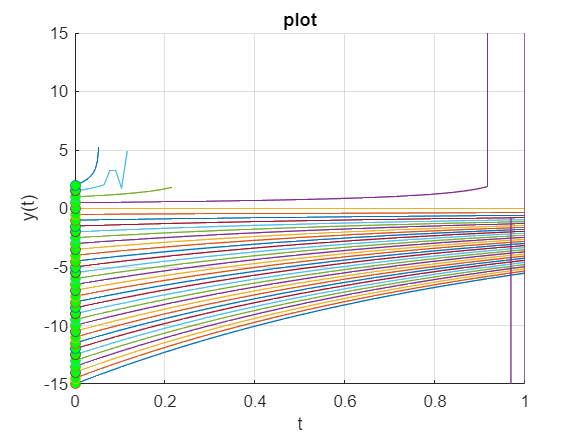

y0 = xi:0.5:2; tspan = [t0,tf]; % initial points of PVI from xi to 2
[ts,ys] = ode45(fN_lmb,tspan,y0); % for computing trajectories

figure;hold on;
plot(ts,ys); plot(0,y0,'o','MarkerFaceColor','g');
axis([t0,tf,xi,xf])
xlabel('t');ylabel('y(t)');grid on; title('plot')
% Plot an aditional trajectory initialize at 2.001
[ts,ys] = ode45(fN_lmb,tspan, 2.001);
plot(ts,ys); plot(0,y0,'o','MarkerFaceColor','g');